# Laboratorio final robótica 2021-1

### UNAL 

Kevin Andres Ramirez Gutierrez - 

David Andrés Rivas Gonzalez - 

Jefferson David Rojas Avellaneda - jedrojasav

Manuel Alejandro Rojas Cubillos - 

### Modelos

- Se hace el análisis geométrico del robot y se llega a la siguiente tabla de parámetros DHmod:

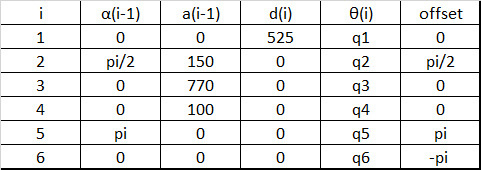

Una vez obtenida la tabla se procede a crear el modelo del robot usando el toolbox de peter corke por medio de las funciones Link y serialLink

clear; clc;
l1 = 525; l2=150; l3=770; l4=100; l5=740; l6=100; 
q1 = 0; q2=0; q3=0; q4=0; q5=0; q6=0;  % Valores Home 
q =  [q1 q2 q3 q4 q5 q6];

ws = [-1500 1500 -1500 1000 -50 2400];
plot_options = {'workspace',ws,'scale',.5,'view',[135 45],'tilesize',2,'ortho','lightpos',[100 100 100]};

L(1) = Link('revolute', 'alpha', 0,     'a',  0,    'd',    l1, 'offset',       0,  'qlim', [-pi pi],'modified');
L(2) = Link('revolute', 'alpha', pi/2,  'a', l2,    'd',    0,  'offset',    pi/2,  'qlim', [-pi/2 8*pi/9], 'modified') ;
L(3) = Link('revolute', 'alpha', 0,     'a', l3,    'd',    0,  'offset',       0,  'qlim', [-17*pi/18 29*pi/18], 'modified');
L(4) = Link('revolute', 'alpha', pi/2,  'a', l4,    'd',    l5,  'offset',       0,  'qlim', [-10*pi/9 10*pi/9], 'modified');
L(5) = Link('revolute', 'alpha', pi/2,  'a',  0,    'd',    0,  'offset',     pi,  'qlim', [-7*pi/4 7*pi/4], 'modified');
L(6) = Link('revolute', 'alpha', pi/2,  'a',  0,    'd',    l6,  'offset',   pi/2,  'qlim', [-5*pi/2 5*pi/2], 'modified');

Robot = SerialLink (L,'name','Fanuc','plotopt',plot_options)

 
Robot = 
 
Fanuc (6 axis, RRRRRR, modDH, fastRNE)                           
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        525|          0|          0|          0|
|  2|         q2|          0|        150|      1.571|      1.571|
|  3|         q3|          0|        770|          0|          0|
|  4|         q4|        740|        100|      1.571|          0|
|  5|         q5|          0|          0|      1.571|      3.142|
|  6|         q6|        100|          0|      1.571|      1.571|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

Se observa que la tabla de parámetros obtenida es igual a la que se planteó en un inicio por lo que se procede a ver el robot en forma gráfica:

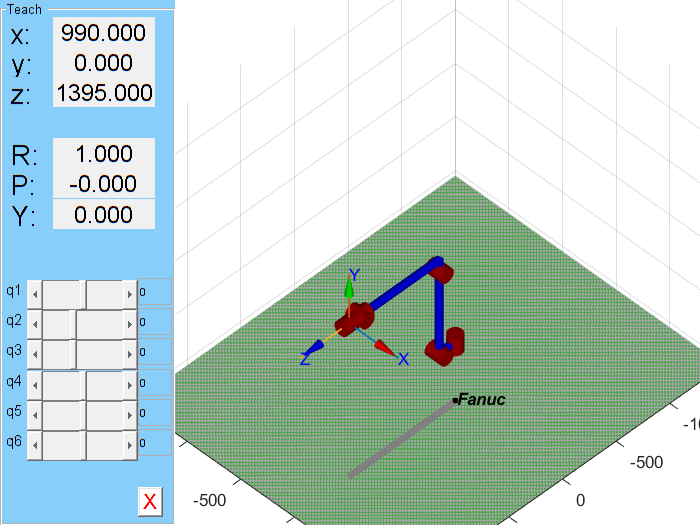

Robot.teach(q)

### Modelo geométrico directo

### Modelo geométrico inverso

### Modelo diferencial de primer orden